## 文件的初始化工作 

clear;
close all;
clc;
rng(2023);              %固定随机种子，保证结果可复现

## 参数设置

V_max = 1;              %量化范围[-V_max, V_max]
Q_bit = [1,2,3];        %量化比特数
V = 1;                  %均匀分布的范围[-V, V]
N = 1000000;            %均匀分布下采样点数
s = -V+2*V*rand(1,N);   %均匀分布下的采样
s_hat = zeros(size(s)); %量化后的重建采样储存数组

## 画出均匀分布生成采样的幅度分布

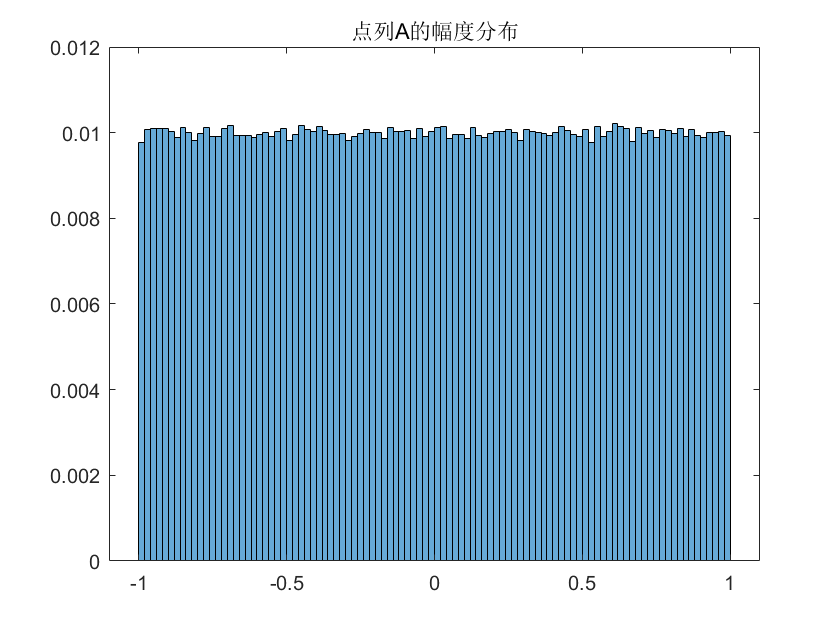

bins = 100;             %选取合理的直方图格点数
histogram(s, bins,'Normalization','probability');
title("点列A的幅度分布");

## 实验内容

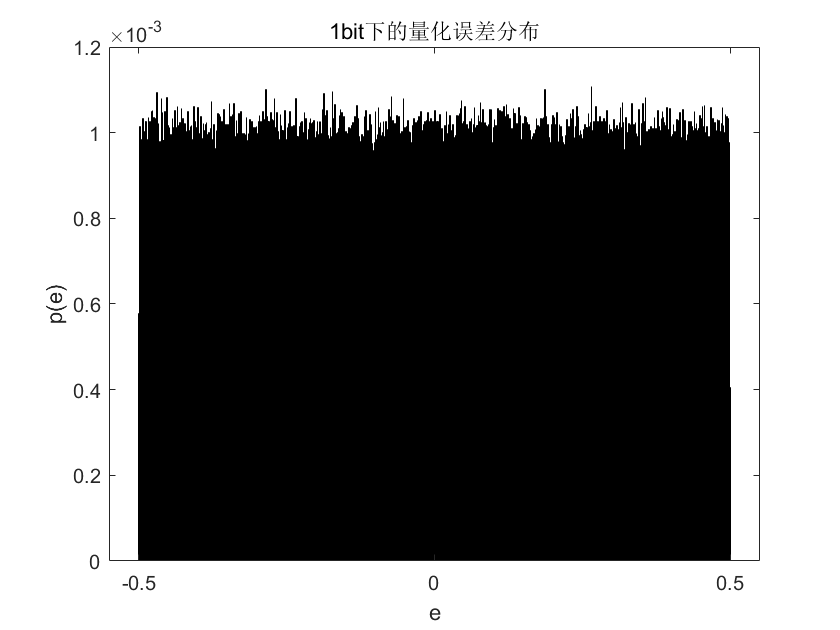

1bit量化时,噪声方差理论值/实际值=0.083334/0.083314,信号功率理论值/实际值=0.333343/0.333361,量化信噪比理论值/实际值=6.020687/6.021983dB


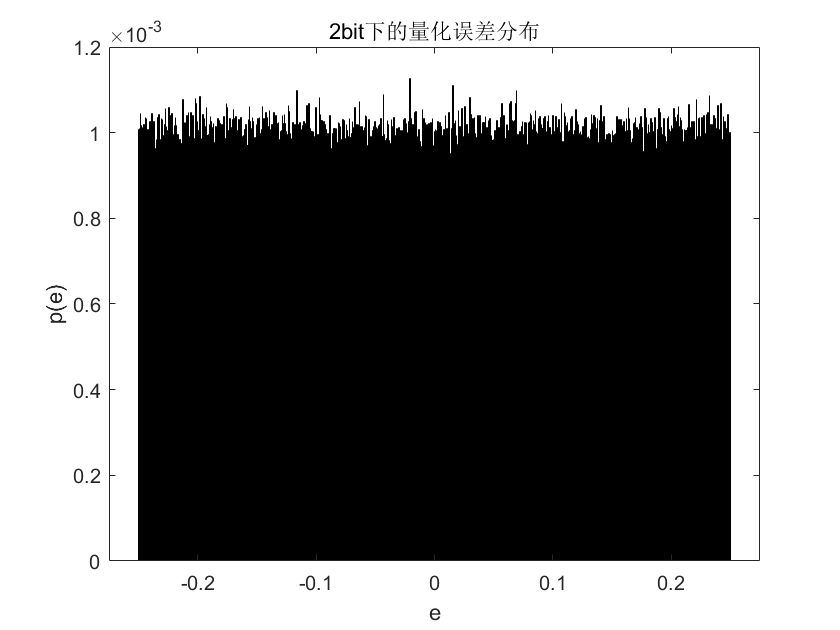

2bit量化时,噪声方差理论值/实际值=0.020834/0.020835,信号功率理论值/实际值=0.333343/0.333361,量化信噪比理论值/实际值=12.041287/12.041238dB


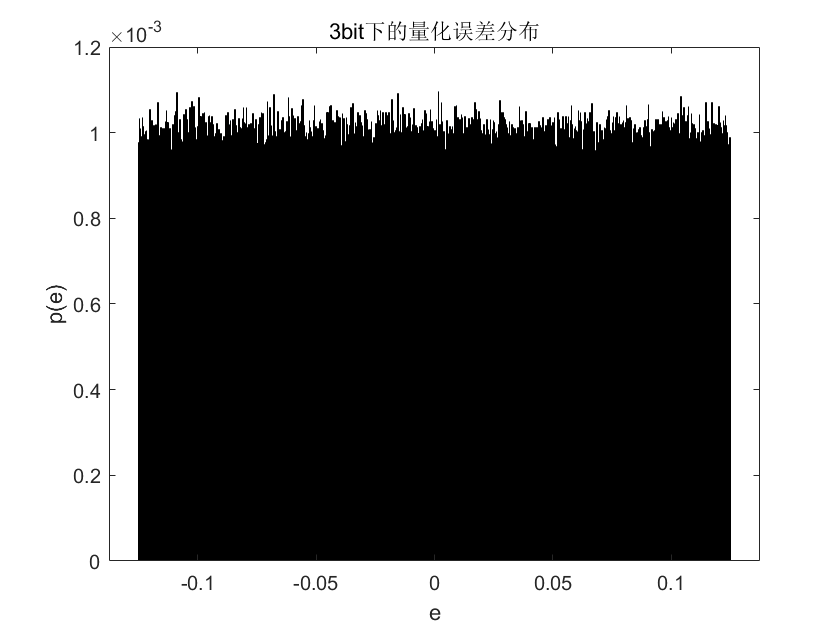

3bit量化时,噪声方差理论值/实际值=0.005208/0.005204,信号功率理论值/实际值=0.333343/0.333361,量化信噪比理论值/实际值=18.061887/18.065424dB


for B = Q_bit                                           %量化比特数1/2/3bit
    
    L = 2^B;                                            %量化区间数目
    interval = 2*V/(2^B);                               %量化间隔
    x = [-V:interval:V];                                %分层电平[x_1,x_2,..,x_{L+1}]
    y = [(x(1)+x(2))/2:interval:(x(L)+x(L+1))/2];       %重建电平[y_1,y_2,...,y_L]
    
    %%%%%%%%%% 理论计算(概率值直接用理论理想的结果即可)%%%%%%%%%%%%%%%%%%%%
    noise_th = 0;                                       %量化噪声方差(理论值)
    point_num=100000;
    int_itv=2*V/point_num;
    for i=0:point_num
        noise_th=noise_th+(V^2/3/(L^2))*0.5*int_itv;        
    end    
    power_th = 0;                                       %信号功率(理论值)
    for i=0:point_num
        power_th=power_th+((i-point_num/2)*int_itv)^2*0.5*int_itv;
    end
    snr_th = power_th/noise_th;                         %信噪比(理论值)
    snrdb_th = 10*log10(snr_th);                        %信噪比dB(理论值)
    
    %%%%%%%%%% 实验计算(用实验生成的采样计算结果)%%%%%%%%%%%%%%%%%%%%%%%%
    %%通过计算量化后的采样s_hat,计算量化误差e(x)    
    if(B==1)
        s_hat=(double(s>=x(1)&s<=x(2))*y(1) + double(s>=x(2)&s<=x(3))*y(2));
    elseif(B==2)
        s_hat=(double(s>=x(1)&s<=x(2))*y(1) + double(s>=x(2)&s<=x(3))*y(2) + ...
            double(s>=x(3)&s<=x(4))*y(3) + double(s>=x(4)&s<=x(5))*y(4));
    elseif(B==3)
        s_hat=(double(s>=x(1)&s<=x(2))*y(1) + double(s>=x(2)&s<=x(3))*y(2) + ...
            double(s>=x(3)&s<=x(4))*y(3) + double(s>=x(4)&s<=x(5))*y(4) + ...
            double(s>=x(5)&s<=x(6))*y(5) + double(s>=x(6)&s<=x(7))*y(6) + ...
            double(s>=x(7)&s<=x(8))*y(7) + double(s>=x(8)&s<=x(9))*y(8));
    end
    ex=s-s_hat;
    power_exp = sum(s.^2)/N;                            %信号功率(实际值)    
    noise_exp = sum(ex.^2)/N;                           %量化噪声方差(实际值)
    
    snr_exp = power_exp/noise_exp;                      %量化信噪比(实际值)
    snrdb_exp = 10*log10(snr_exp);                      %量化信噪比dB(实际值)

    
     %%%%%%%%% 输出 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
     figure;
     exbins=1000; %选取合理的直方图格点数
     histogram(ex,exbins,'Normalization','probability'); %计算e(x)的分布
     title(num2str(B)+"bit下的量化误差分布")
     xlabel("e")
     ylabel("p(e)")     
     fprintf("%dbit量化时,噪声方差理论值/实际值=%f/%f,信号功率理论值/实际值=%f/%f,量化信噪比理论值/实际值=%f/%fdB\n",B,noise_th,noise_exp,power_th,power_exp,snrdb_th,snrdb_exp);
end